load('matlab_output_LFPo09.mat')
% inspect table
head(bpodTable)

rng(1000)
M = randn(5, 1)

A = M > 0;
A(A == 0) = [];

fig = plot(A);
fig.Marker = 'h';
fig.MarkerSize = 12;
fig.LineStyle = "none";
fig.MarkerFaceColor = "y";
fig.MarkerEdgeColor = "r";
ylim([-0.2 1.2])

ax = gca;
ax.XAxis.Visible = "off";
ax.YAxis.Visible = "off";

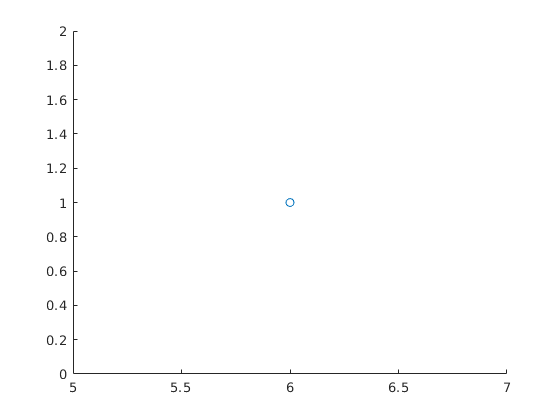

for i = 1: length(A)
    if A(i) == 1;
        scatter(i, A(i))
    end
end

function [RightCount, Total, PercentCorrect] = groupByTrialType(x)

RightCount = nnz(x == 2);
Total = numel(x);
PercentCorrect = RightCount ./ Total;

end

% Function to bootstrap and fit to a logistic regression
function bfit = glmBfit(diff, perf)

bfit = glmfit(diff, perf, "binomial", "link","logit");

end

% Function to plot the data

function PlotPsychFunction(difficulty, performance,range_for_logitFit, logitFit,dylo, dyhi)

ax = gca;

hold on

plot(difficulty, performance, "ob", "MarkerFaceColor", "b")
plot(range_for_logitFit, logitFit, "k-")
plot(range_for_logitFit, logitFit - dylo, "r--")
plot(range_for_logitFit, logitFit + dyhi, "r--")

xAx = ax.XAxis;
xAx.Direction = "reverse";
hold off

end

function PlotPsychFunctionBtStrp(difficulty, performance,range_for_logitFit, logitFit,dylo, dyhi) 

ax = gca;
% c = uisetcolor;
c = [0.75 0.73 0.99];
hold on

for i = 1:100
    b2 = bootstrp(1, @glmBfit, difficulty, performance);
    yfitBoot(:, i) = glmval(b2', range_for_logitFit, "logit");
    plot(range_for_logitFit, yfitBoot(:, i), '-', "Color", c);  
end

plot(difficulty, performance, "ob", "MarkerFaceColor", "b")
plot(range_for_logitFit, logitFit, "k-")
plot(range_for_logitFit, logitFit - dylo, "r--")
plot(range_for_logitFit, logitFit + dyhi, "r--")

% h = findobj(gca,'Type','line');
xAx = ax.XAxis;
xAx.Direction = "reverse";
hold off

end